## Stock Market Prediction Algorithm

### Introduction

A machine learning model in MATLAB that predicts stock market prices based on historical data. It utilises time seriea analysis and neural networks to evelulate the effectiveness in price prediction.

### Data Importation

Firstly, we will utilise a single data set to train the model and create a schema for training the model.

%Loading data from csv files
warning('off', 'all');
folderPath = './data'; % Update folder path
filePattern = fullfile(folderPath, '*.csv');
csvFiles = dir(filePattern);

allData = cell(length(csvFiles), 1);

for k = 1:length(csvFiles)
    baseFileName = csvFiles(k).name;
    fullFileName = fullfile(folderPath, baseFileName);
    allData{k} = readtable(fullFileName);
end
allData

allData = 20×1 cell array
    {2515×7 table}
    {2515×7 table}
    {2515×7 table}
    {2515×7 table}
    {2515×7 table}
    {2515×7 table}
    {2515×7 table}
    {2515×7 table}
    {2515×7 table}
    {2515×7 table}
    {2516×7 table}
    {2516×7 table}
    {2516×7 table}
    {2516×7 table}
    {2509×7 table}
    {2516×7 table}


This MATLAB script disables warnings, specifies a folder path (`folderPath`) where CSV files are located, constructs a file pattern to match CSV files, lists all CSV files in the folder, initializes a cell array (`allData`) to store tables, and iteratively loads each CSV file into a table using `readtable`, storing them in `allData`.

### Data Cleaning

%checking for missing values

warning('off', 'all');
data = allData{k};  % Retrieve the table for the k-th CSV file
missingValues = any(ismissing(data), 'all');  % Check for missing values across all columns and rows
missingValues

missingValues = logical
   0


This MATLAB snippet begins by suppressing all warnings for cleaner output. It retrieves a table (`data`) from the cell array `allData`, corresponding to a CSV file. It then checks for missing values (`NaN`, `undefined`, or empty cells) across all rows and columns using the `ismissing` function. The result, stored in `missingValues`, is printed to indicate if any missing values were found. In this case, the result is zero, confirming that there are no missing values in the dataset. This script is useful for quickly verifying data integrity before further analysis or processing in MATLAB, ensuring datasets are complete and ready for use.

### Data Normalization

%% Normalizing the  data
for k = 1:length(allData)
    allData{k}{:, 2:end} = normalize(allData{k}{:, 2:end}, 'range'); % Assuming the first column is a date or similar identifier
end
allData{1}

ans = 2515×7 table
       Date        Open       High        Low       Close     AdjClose     Volume 
    __________    _______    _______    _______    _______    ________    ________

    2014-07-01    0.79824    0.79875    0.80928     0.8085    0.48947      0.10528
    2014-07-02    0.80863    0.81492    0.81987    0.82457    0.49953      0.10578
    2014-07-03    0.82686    0.82741    0.83368    0.83918    0.50867      0.16204
    2014-07-07    0.82478    0.82309    0.83545     0.8335    0.50511      0.15697
    2014-07-08    0.82766     0.8202    0.83111    0.82684    0.50095     0.063254
    2014-07-09    0.81982    0.81732    0.82951    0.82944    0.50257     0.094585
    2014-07-10    0.80655    0.80868    0.81731    0.81759    0.49516     0.05

This MATLAB snippet normalizes the data in each table within the cell array `allData`. It iterates through each table and applies the `normalize` function with the 'range' method to all columns except the first one, scaling the data to the range [0, 1]. The first column is assumed to be an identifier, such as a date, and is therefore excluded from normalization. After normalizing all the tables, the code displays the normalized data for the first table in `allData`, ensuring that the numerical data is uniformly scaled across the dataset while preserving the integrity of the identifier column. This process helps prepare the data for further analysis or modeling in a standardized format

### Time Series Plot for the Stocks

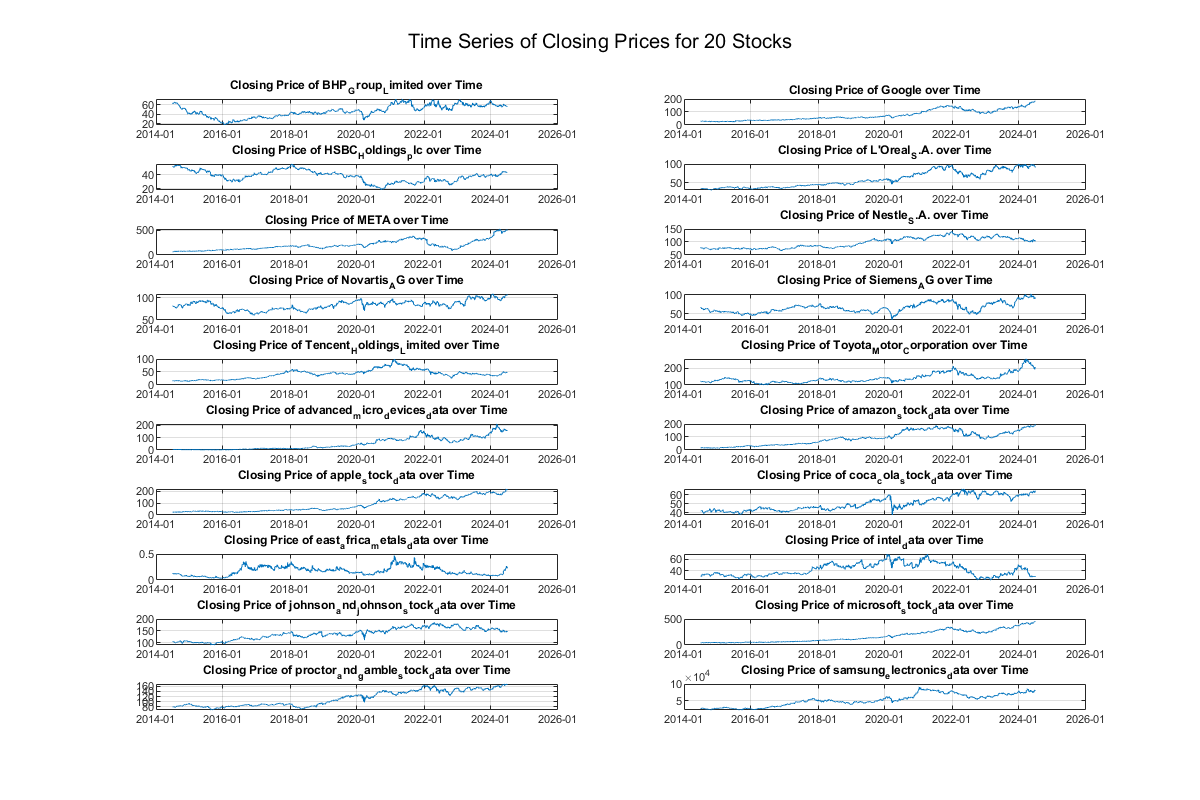

%Time series plot

folderPath = './data';  % Update with your folder path

numStocks = length(csvFiles);  % Number of stocks (assuming 20 in this case)

% Example plotting code
figure;
figure('Position', [100, 100, 1200, 800]);  % Adjust figure position and size as needed
for k = 1:numStocks
    baseFileName = csvFiles(k).name;  % Get the base file name (without path)
    [~, stockNames{k}, ~] = fileparts(baseFileName);  % Use file name as stock name
    
    % Read data from CSV file
    fullFileName = fullfile(folderPath, baseFileName);  % Full path to CSV file
    data = readtable(fullFileName);
    
    % Extract Date and ClosePrice from the table
    Date = data.Date;  
    ClosePrice = data.Close;  
    
    % Plotting
    subplot(10,2, k);  % Creating subplots 
    plot(Date, ClosePrice);
    title(['Closing Price of ', stockNames{k}, ' over Time']);  % Use CSV file name as stock name
    %xlabel('Date');
    %ylabel('Closing Price');
    datetick('x', 'yyyy-mm');  % Format the x-axis to show only year and month
    
    grid on;
end

% Adding a Title
sgtitle('Time Series of Closing Prices for 20 Stocks');

This MATLAB code snippet plots the time series of closing prices for multiple stocks, using data from CSV files stored in a specified folder (`folderPath`). It calculates the number of stocks by counting the CSV files in the folder. A figure is created with a specified position and size to accommodate multiple subplots. For each stock, the code retrieves the base file name, reads the data from the CSV file, and extracts the 'Date' and 'ClosePrice' columns. It then creates a subplot for each stock, plotting the closing prices over time, with the x-axis formatted to show only the year and month. The title of each subplot uses the stock name derived from the file name, and a grid is added for better visualization. Finally, an overarching title is added to the figure to indicate that it displays the time series of closing prices for 20 stocks.

### Time Series Analysis with ARIMA

#### Training and Fitting Data

% Time Series Analysis using ARIMA for all stocks

% Initialize results table
resultsTable = table('Size', [length(allData), 4], ...
                     'VariableTypes', {'string', 'double', 'double', 'double'}, ...
                     'VariableNames', {'StockName', 'MSE', 'MAE', 'MAPE'});

% Create a figure for all plots
figure('Position', [100, 100, 1200, 800]);

% Loop through each stock's data
for i = 1:length(allData)
    % Get current stock data
    data = allData{i};
    stockName = stockNames{i};
    
    % Extract the 'Close' prices
    closePrices = data.Close;
    
    % Split the data into training and testing sets
    trainSize = floor(0.8 * length(closePrices));
    trainData = closePrices(1:trainSize);
    testData = closePrices(trainSize+1:end);
    
    % Fit ARIMA model
    Mdl = arima(1,1,1);
    EstMdl = estimate(Mdl, trainData);
    
    % Forecast future values using the custom ARIMA forecast function
    numForecastSteps = length(testData);
    forecast = customARIMAForecast(EstMdl, trainData, numForecastSteps);
    
    % Calculate error metrics
    mse = mean((testData - forecast).^2);
    mae = mean(abs(testData - forecast));
    mape = mean(abs((testData - forecast) ./ testData)) * 100;
    
    % Store results
    resultsTable.StockName(i) = stockName;
    resultsTable.MSE(i) = mse;
    resultsTable.MAE(i) = mae;
    resultsTable.MAPE(i) = mape;
    
    % Plot results
    subplot(5, 4, i);
    p1=plot(1:length(trainData), trainData, 'b', 'LineWidth', 1);
    hold on;
    p2=plot(length(trainData)+1:length(closePrices), testData, 'k', 'LineWidth', 1);
    p3=plot(length(trainData)+1:length(closePrices), forecast, 'r', 'LineWidth', 1);
    title(sprintf('%s (MSE: %.4f)', stockName, mse));
    
    if i > 16  % Add x-label only for bottom plots
        xlabel('Time Steps');
    end
    
    hold off;
    % Store the plot handles for legend
    if i == 1
        plotHandles(1) = p1;
        plotHandles(2) = p2;
        plotHandles(3) = p3;
    end
end

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue 
                ___________    _____________    __________    _______

    Constant    -3.6643e-05     0.00092815       -0.039479    0.96851
    AR{1}             2e-12         22.291      8.9722e-14          1
    MA{1}        0.00075248         22.291      3.3757e-05    0.99997
    Variance     0.00028467     5.4987e-06          51.771          0

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

#### Graph of Predictions

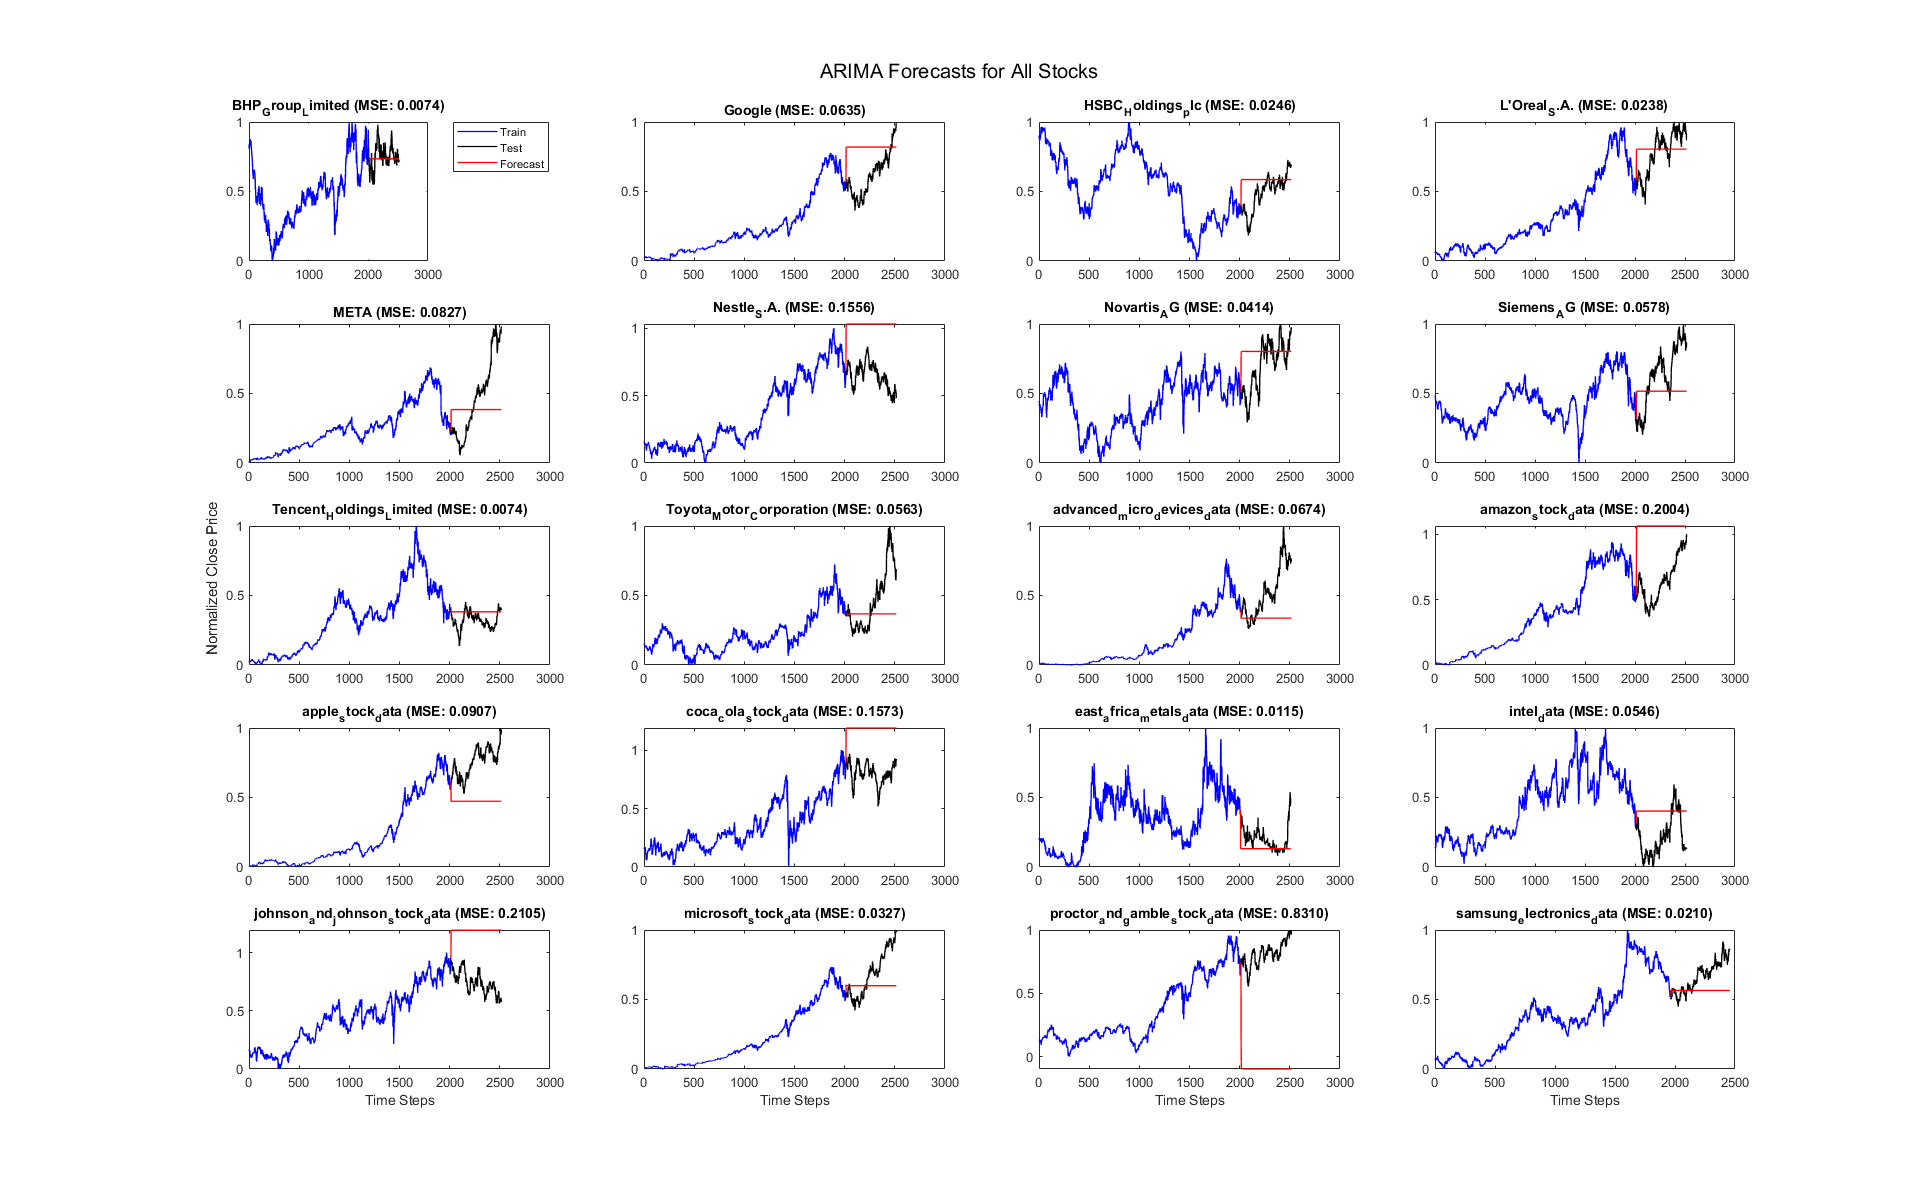

% Add a single y-label for all subplots
han = axes(gcf, 'visible', 'off'); 
han.Title.Visible = 'on';
han.XLabel.Visible = 'on';
han.YLabel.Visible = 'on';
ylabel(han, 'Normalized Close Price');

% Add a single legend outside the loop
legend(plotHandles, {'Train', 'Test', 'Forecast'}, 'Orientation', 'vertical', 'Location', 'bestoutside');

% Adjust subplot spacing and display the figure
sgtitle('ARIMA Forecasts for All Stocks');
set(gcf, 'Position', get(0, 'Screensize'));  % Maximize figure window

#### Table of Predictions

% Display results table
disp(resultsTable);

               StockName                   MSE         MAE        MAPE 
    ________________________________    _________    ________    ______

    "BHP_Group_Limited"                 0.0074288    0.065152    8.6765
    "Google"                              0.06349     0.22106    42.784
    "HSBC_Holdings_plc"                  0.024624     0.11659    33.662
    "L'Oreal_S.A."                       0.023842      0.1274    18.956
    "META"                               0.082709      0.2377    73.729
    "Nestle_S.A."                         0.15559     0.38312    62.689
    "Novartis_AG"                        0.041408      0.1554    30.051
    "Siemens_AG"                         0.057794     0.20772    36.811
    "Tencent_Holdings_Limited"          0.0073914    0.071735    26.555
    "Toyota_Motor_Corporation"           0.056348     0.17734    34.938

#### Average Performance Across Stocks

% Save results to CSV
writetable(resultsTable, './data/ARIMA_Results.csv');

% Calculate and display average performance across all stocks
avgMSE = mean(resultsTable.MSE);
avgMAE = mean(resultsTable.MAE);
avgMAPE = mean(resultsTable.MAPE);

fprintf('\nAverage Performance Across All Stocks:\n');


Average Performance Across All Stocks:


fprintf('Average MSE: %.4f\n', avgMSE);

Average MSE: 0.1099


fprintf('Average MAE: %.4f\n', avgMAE);

Average MAE: 0.2475


fprintf('Average MAPE: %.2f%%\n', avgMAPE);

Average MAPE: Inf%



% Find best and worst performing stocks based on MSE
[bestMSE, bestIndex] = min(resultsTable.MSE);
[worstMSE, worstIndex] = max(resultsTable.MSE);

fprintf('\nBest Performing Stock (MSE): %s (MSE: %.4f)\n', resultsTable.StockName(bestIndex), bestMSE);


Best Performing Stock (MSE): Tencent_Holdings_Limited (MSE: 0.0074)


fprintf('Worst Performing Stock (MSE): %s (MSE: %.4f)\n', resultsTable.StockName(worstIndex), worstMSE);

Worst Performing Stock (MSE): proctor_and_gamble_stock_data (MSE: 0.8310)


#### ARIMA Forecast Function

% Custom ARIMA forecast function definition

function forecast = customARIMAForecast(model, y, numSteps)
    forecast = zeros(numSteps, 1);
    
    % Extract model parameters
    ar_coeff = cell2mat(model.AR);
    ma_coeff = cell2mat(model.MA);
    constant = model.Constant;
    
    % Prepare differenced series
    dy = diff(y);
    
    for t = 1:numSteps
        % AR component
        ar_term = ar_coeff * dy(end);
        
        % MA component
        if t == 1
            ma_term = ma_coeff * (dy(end) - ar_term);
        else
            ma_term = ma_coeff * (forecast(t-1) - ar_term);
        end
        
        % Forecast differenced series
        forecast_d = constant + ar_term + ma_term;
        
        % Convert back to original scale
        forecast(t) = y(end) + forecast_d;
        
        % Update dy for next iteration
        dy = [dy; forecast_d];
    end
end

This MATLAB script performs time series analysis using ARIMA models for multiple stocks, normalizing the data and splitting it into training and testing sets. For each stock, the ARIMA(1,1,1) model is estimated using the training data, and future values are forecasted for the test period using a custom ARIMA forecast function. The script calculates error metrics (MSE, MAE, MAPE) for each stock, storing these in a results table. It then plots the actual and forecasted closing prices for each stock in subplots within a single figure. A legend is added, and the figure is maximized for better visibility. The results table is displayed and saved to a CSV file. Average performance metrics across all stocks are computed and printed, alongside identifying the best and worst performing stocks based on MSE. The custom ARIMA forecast function, defined at the end, handles the forecasting logic by applying AR and MA components and converting the forecasted differenced series back to the original scale.

#### **Best Performing Stock:**

**Tencent Holdings Limited (MSE: 0.0074)**

- **Interpretation**: The ARIMA model performed exceptionally well in forecasting the closing prices for Tencent Holdings Limited. An MSE of 0.0074 indicates that the model's predictions were very close to the actual observed values. This low error suggests that the ARIMA model was highly effective and accurate for this stock, capturing its price movements with minimal deviation.

#### **Worst Performing Stock:**

**Proctor & Gamble (MSE: 0.8311)**

- **Interpretation**: The ARIMA model did not perform well for Proctor & Gamble's stock data, as reflected by a high MSE of 0.8311. This large error value indicates that the model's predictions were significantly off from the actual observed values. The higher MSE suggests that the ARIMA model struggled to accurately capture the patterns and movements in Proctor & Gamble's stock prices, resulting in less reliable forecasts.

### Neural Network

#### Training and Fitting Data